# lora sim

symbol time caclulator

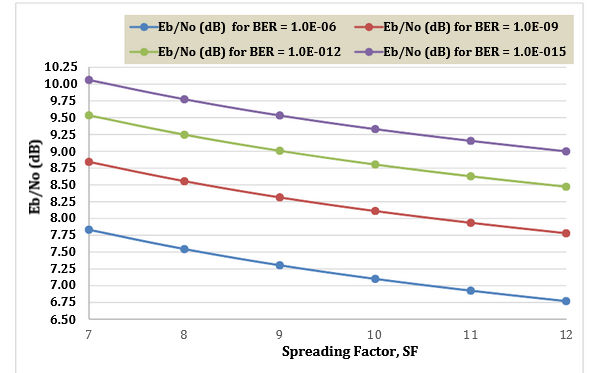

## lora parameters

clear
SF=7;
numSym=10;
BW=125e3;%samples per sec
Fs=BW;
SPS=(2^SF);%samples per lora symbol



## simulation parameters

dataLength=SF*numSym;
randomData=true;
nLoops=30;
filtersOn=false;
plotSpec=false;
maxSNR=120;
dopplerShift=10e3;


## transmitter

%generate data
if randomData
    messageBits= randi([0 1],dataLength,1)
else
    messageBits=ones(dataLength,1)
end

messageBits =      0
     0
     0
     0
     0
     0
     1
     1
     0
     0


messageSymbols=reshape(messageBits,[],SF)%group in symbols, SF bits per symbol

messageSymbols =      0     1     1     1     0     1     0
     0     0     0     0     0     0     1
     0     0     0     0     1     0     1
     0     1     0     1     0     1     1
     0     0     0     1     1     0     0
     0     0     1     0     1     0     0
     1     1     0     1     1     0     1
     1     0     1     0     1     1     1
     0     0     1     0     0     0     1
     0     1     0     0     0     0     0


decimalSymbols=binaryVectorToDecimal(messageSymbols)%to check the value

decimalSymbols =     58
     1
     5
    43
    12
    20
   109
    87
    17
    32


loraSymbols=zeros(SPS,numSym);%%every colum contains the samples of one symbol
for m=1:numSym
    k=binaryVectorToDecimal(messageSymbols(m,:));
    for n=1:SPS
        if k >= SPS %wrap around by 2^SF
            k=k-SPS;
        end 
        k = k+1;
        loraSymbols(n,m)=(1/(sqrt(2^SF)))*exp(1i*2*pi*k*(k/(2^SF*2)));
    end
end

txSignal=reshape(loraSymbols,[],1);

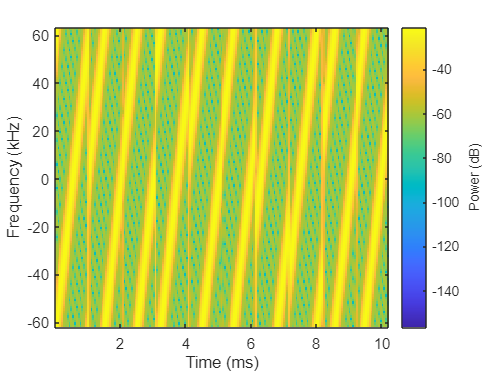

%plot
spectrogram(txSignal(1:10*(2^SF)),round((2^SF)/10),round(((2^SF)/10)/2),2^SF,Fs,'power','centered', 'yaxis');

## channel

SNR = 120

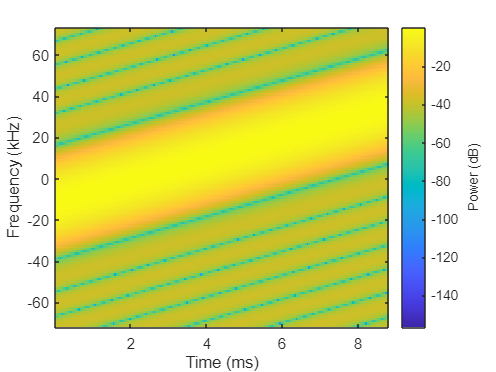

errors=zeros(1,nLoops);
for counter=1:nLoops
    SNR=maxSNR-(counter-1);
symbolDuration=(2^SF)/Fs;

t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);
freqShift=linspace(-dopplerShift,dopplerShift,length(t));
dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
txSignalDopplerShifted = transpose(awgn(txSignal,SNR)).* (dopplerEffect);


if counter==1
    SNR
    hold off
    spectrogram(txSignalDopplerShifted(1:10*(2^SF)),round((2^SF)/10),round(((2^SF)/10)/2),2^SF,Fs+2*dopplerShift,'power','centered', 'yaxis');
    spectrogram(exp(1i * 2 * pi * t),round((2^SF)/10),round(((2^SF)/10)/2),2^SF,Fs+2*dopplerShift,'power','centered', 'yaxis');

end

    spectrogram((exp(1i * 2 * pi * t).* (dopplerEffect)),round((2^SF)/10),round(((2^SF)/10)/2),2^SF,Fs+2*dopplerShift,'power','centered', 'yaxis');


## receiver

lora_ber =     0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857    0.3857


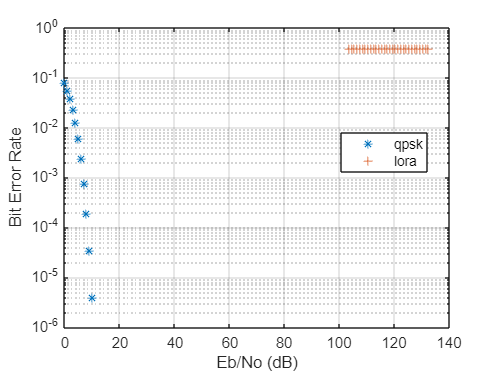

%generate base downchirp
    base_down_chirp=zeros(1,SPS);
    k=0;
    for n=1:SPS
        if k>= (2^SF)
            k=k-2^SF;
        end
        k=k+1;
        base_down_chirp(n)=(1/(sqrt(2^SF)))*exp(-1i*2*pi*k*(k/(2^SF*2)));
    end
dechirpedSymbols=zeros(1,numSym);
for i=1:numSym
    dechirped=txSignalDopplerShifted(((i-1)*SPS)+1:i*SPS).*base_down_chirp;

    corrs=(abs(fft(dechirped)).^2);
    [~, ind]=max(corrs);
    dechirpedSymbols(i)=ind-1; %-1 wantDC wordt meegecount in fft dus alles is +1
   
end
%dechirpedSymbols
decodedBitsMatrix=decimalToBinaryVector(dechirpedSymbols,SF);
decodedBits=reshape(decodedBitsMatrix,[],1);

errors(counter)=sum(decodedBits~=messageBits);
lora_ber(counter)=errors(counter)/dataLength;
SNR_linear=10^(SNR/10);
symbolRate=Fs/SPS;
bitRate =  SF*symbolRate;
EbN0_sim(counter)=10*log10(SNR_linear*Fs/bitRate);
end %of big loop
%errors
lora_ber




EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(EbN0',ber,'*')
hold on
semilogy(EbN0_sim',lora_ber,'+')
legend({'qpsk','lora'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on